# State Space Stirred Reactor

The exercise involves creating a dynamic model based on balance equations, linearizing, and putting the equations into state space form. $A$ reactor is used to convert a hazardous chemical $A$ to an acceptable chemical $B$ in waste stream before entering a nearby lake. This particular reactor is dynamically modeled as a Continuously Stirred Tank Reactor (CSTR) with a simplified kinetic mechanism that describes the conversion of reactant $A$ to product $B$ with an irreversible and exothermic reaction.

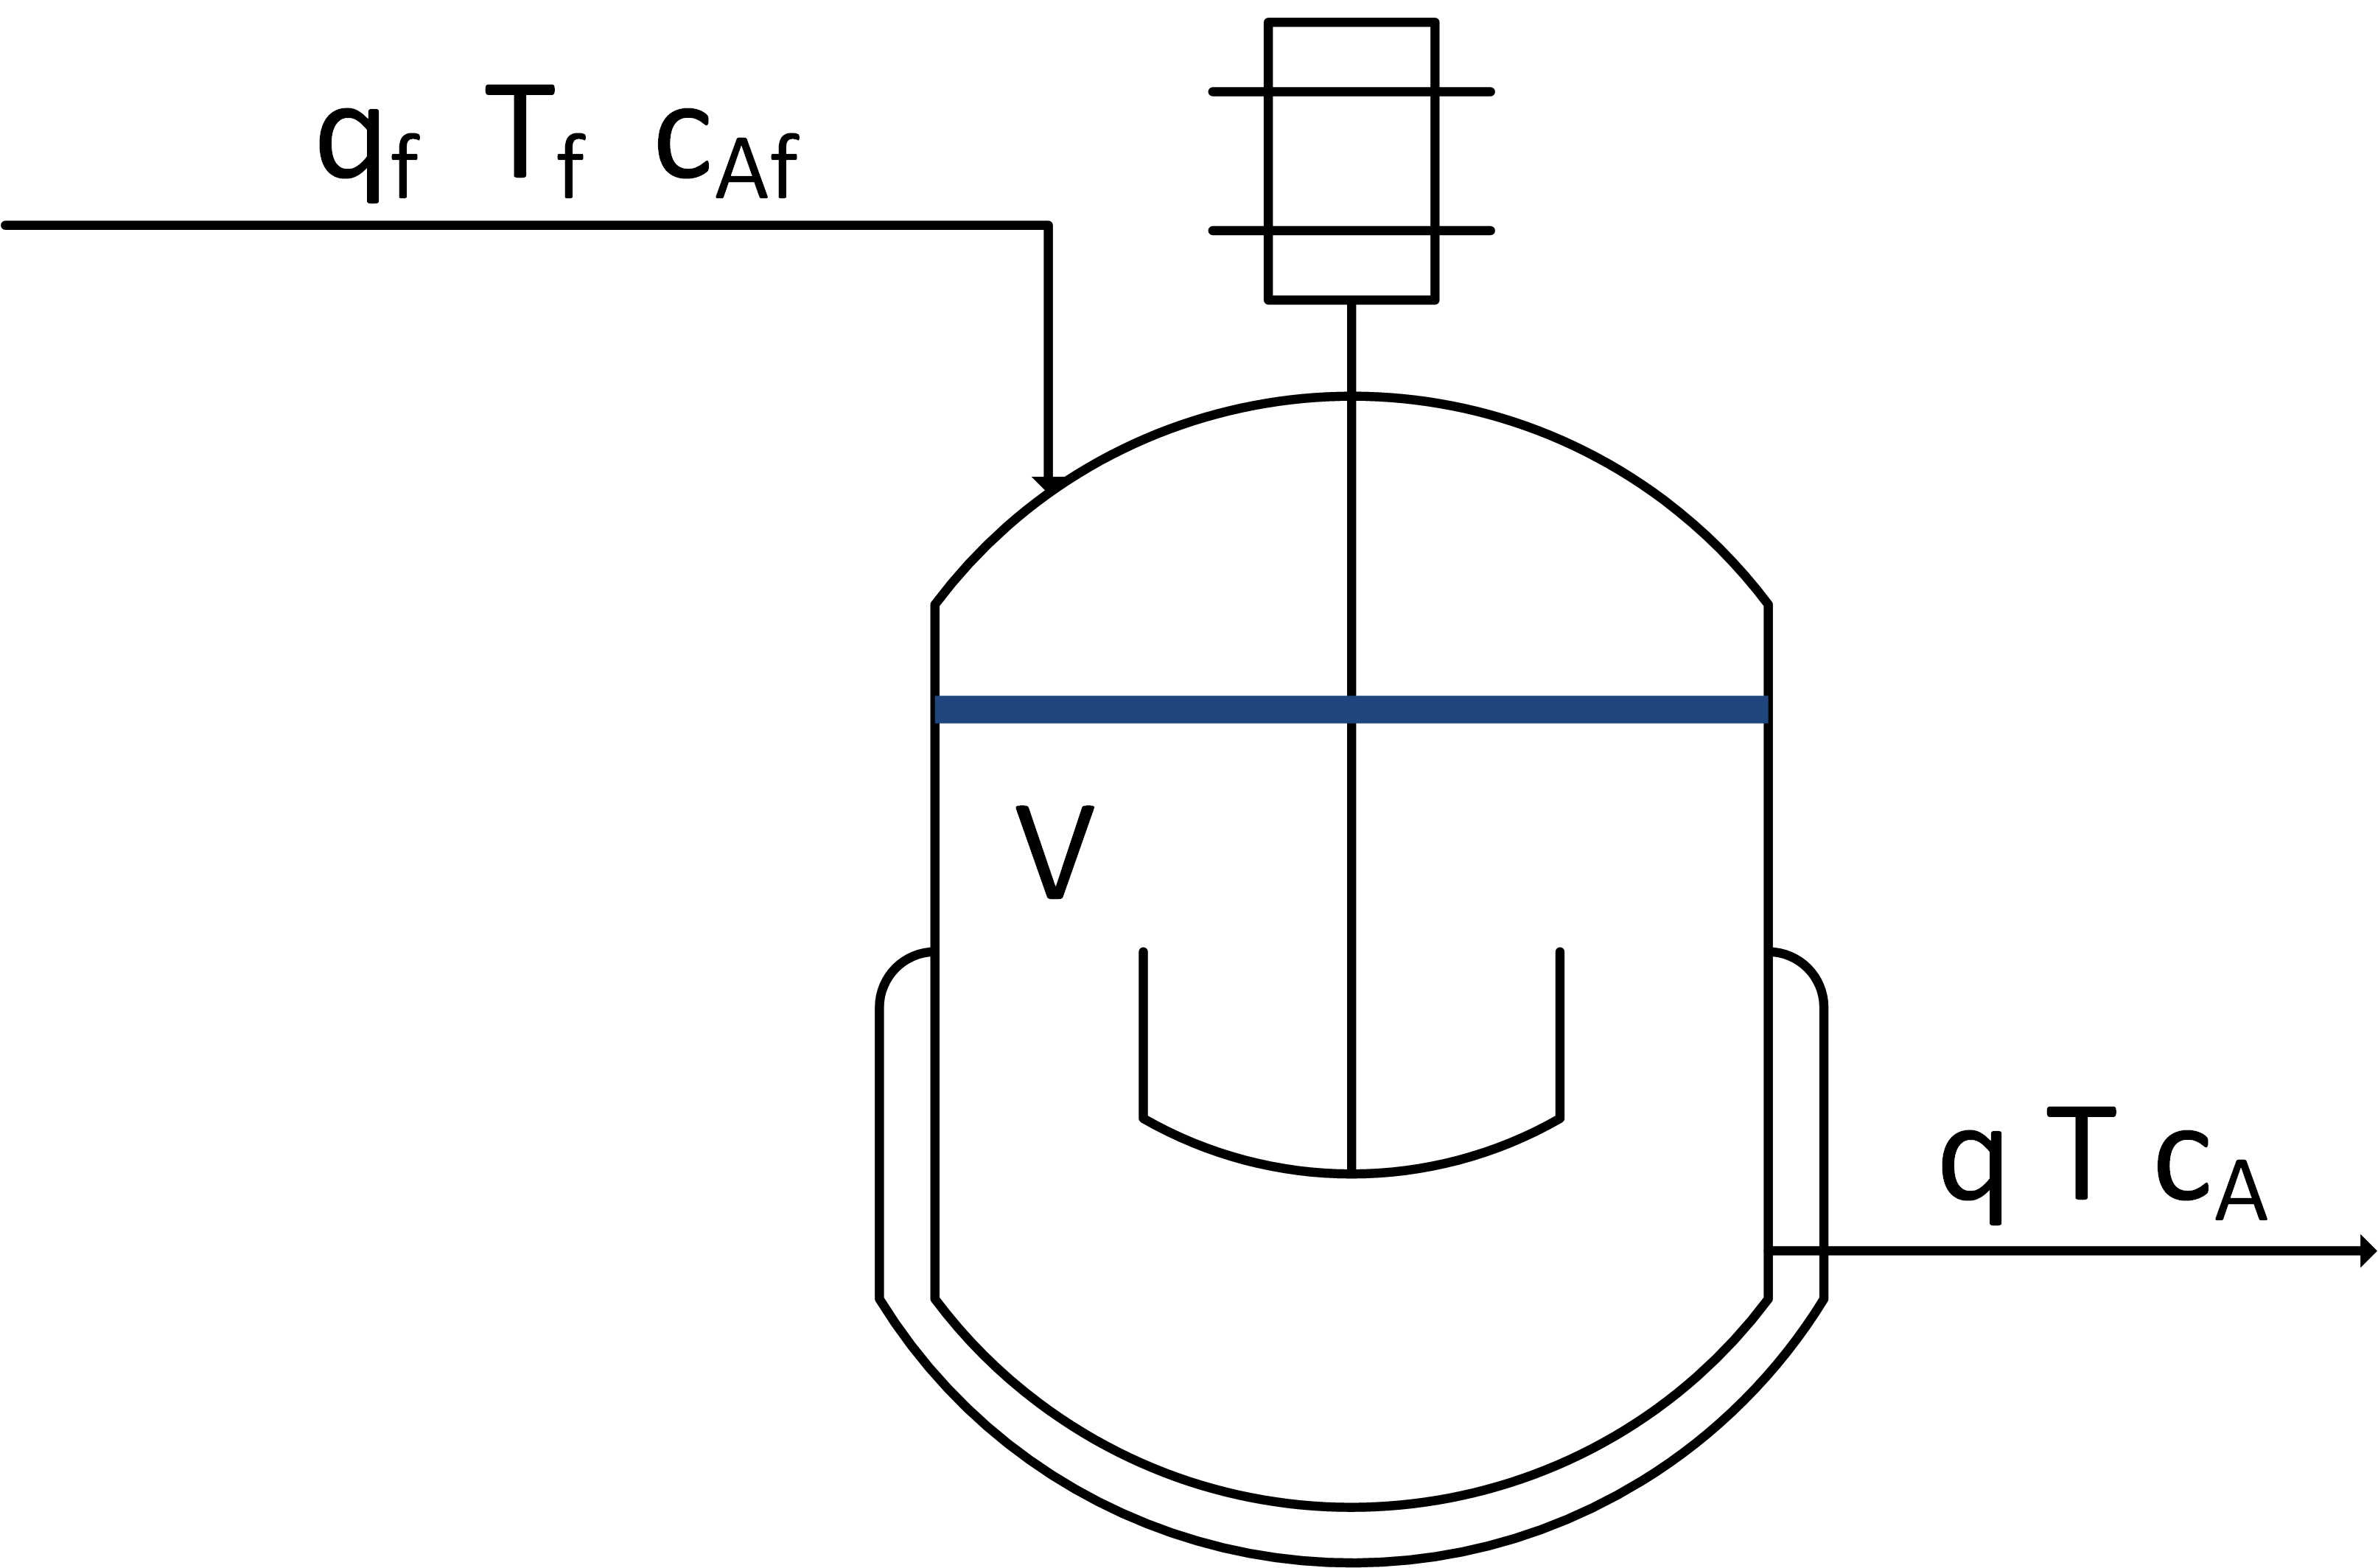

Linearize species and energy balances that describe the dynamic response in concentration and temperature of a well-mixed vessel with constant volume $V=10\text{ m}^3$, volumetric flow $q=5\frac{\text{m}^3}{\text{min}}$, feed temperature $T_f=300 \text{ K}$, initial concentration $C_{A0}=0.5\frac{\text{mol}}{\text{L}}$, and initial temperature $T_0=305\text{ K}$. The chemical $A$ is converted to chemical $B$ with first order reaction kinetics $r_A=0.5 \ C_a$. The reaction is exothermic with a heat of reaction of 10 J/mol. The following species and energy balances represent the reactor concentration and temperature.


$$\frac{dC_a}{dt} = \frac{q}{V} \left(C_{af} - C_a \right) - r_A$$



$$\frac{dT}{dt} = \frac{q}{V} \left(T_f-T\right) + \Delta H_r \; r_A$$


## Starting Script

### Inputs $u$


$$u=\left[\matrix{C_{Af} \cr T_f}\right] $$


### States $x$


$$x=\left[\matrix{C_{A} \cr T}\right] $$


### Outputs $y$


$$\frac{dx}{dt}=Ax+Bu\\y=Cx+Du$$


### Simplified Equations


$$\frac{d\ C_A}{dt}=\frac{(C_{Af}-C_A)}{2}-\frac{C_A}{2} \\
\frac{dT}{dt}=\frac{(T_{f}-T)}{2}+5C_A$$


Create State Space Matricies

n = 2;
m = 1;
p = 2;

A = zeros(n,n);
B = zeros(n,m);

Fill in Linearized equation non-zero elements

A(1,1) =  ;
B(1,1) =  ;
A(2,1) =  ;
A(2,2) =  ;

Define Outputs

C = eye(n);
D = zeros(p,m);

Define State Space Model

sys = ss(A, B, C, D);
Caf = ones(101,1) * 0.9;
x0 = [1;305];
u = [Caf];
t = linspace(0, 10, 101);

[y,x] = lsim(sys, u, t);

Ca_ss = 1;
T_ss = 305;

y_sys = -0.1 * y;
Ca = Ca_ss + y_sys(:,1);
T = T_ss+y_sys(:,2);

Plot the Simulated State Space Model Compared to the TCLab Data

figure()
subplot(2,1,1)
plot(x,Ca)
ylabel('Concentration (M)')
subplot(2,1,2)
plot(x,T)
ylabel('Temperature (K)')
xlabel('Time (s)')

## Solution


$$A_{1,1} = \frac{C_{Af}-C_A}{2}=-0.5(C_A')$$



$$B_{1,1} =0.5C_{Af}$$



$$A_{2,1} = 5(C_{Af}-C_A)=5(C_A')$$



$$A_{2,2} = \frac{T-T_0}{2}=-0.5(T')$$
